format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

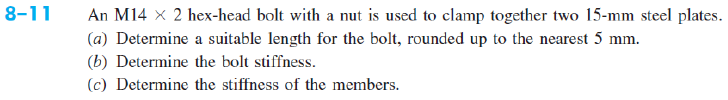

d = 14 * u.mm;
H_b = 9.25 % Højde på bolt hoved (se også table A-31) [mm]

H_b =          9.25


p = 2 * u.mm;
t = 15 * u.mm;              % tykkelse af pladen [mm]
H_m = 12.8 * u.mm;             % Højde på møtrik (se også table A-29) [mm]
R = 0.6;              % Rundingsradius (se også table A-29)[mm]
E = 210 * u. GPa;
l = 2*t

$$l = 30\,\mathrm{mm}$$


L_test = t + t + H_m;          % Gevindlængde  [mm]
L_test_ = vpa(L_test, 3)

$$L\_test\_ = 42.8\,\mathrm{mm}$$


L = 45 * u.mm

$$L = 45\,\mathrm{mm}$$


if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L)<= 200
    L_T = 2 * d + 12
elseif separateUnits(L) > 200
    L_T = 2 * d + 25
else
    disp("Hmmm something is wrong")
end

$$L\_T = 34\,\mathrm{mm}$$


A_d = pi/4 * d^2;   % Skaftareal [mm^2]
A_t = 115 * u.mm^2 %pi/4 * d_t^2; % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t

$$A\_t = 115\,{\mathrm{mm}}^{2}$$

l_d = L - L_T

$$l\_d = 11\,\mathrm{mm}$$

l_t = l - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = 19\,\mathrm{mm}$$



k_d = vpa(unitConvert((A_d * E) / l_d, u.MN), 5) %ligning 8-16

$$k\_d = 2938.8\,\frac{\mathrm{MN}}{m}$$





k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.MN), 5)

$$k\_b = 887.29\,\frac{\mathrm{MN}}{m}$$